circ_rad = 30;
led_rad = 25;
positions = 8;
led_coords = [];
x_cent = 107.5;
y_cent = 77.5;    
for i = 1:positions
   led_coords(i,1) = x_cent + led_rad * cos(i*2*pi/positions);
   led_coords(i,2) = y_cent + led_rad * sin(i*2*pi/positions);
end
led_coords

led_coords =   125.1777   95.1777
  107.5000  102.5000
   89.8223   95.1777
   82.5000   77.5000
   89.8223   59.8223
  107.5000   52.5000
  125.1777   59.8223
  132.5000   77.5000


theta = linspace(0,2*pi);
perim_x = x_cent + circ_rad * cos(theta);
perim_y = y_cent + circ_rad * sin(theta);
scatter(led_coords(:,1), led_coords(:,2),'gs', 'LineWidth',15)
hold on
plot(perim_x,perim_y)
axis equal
mounting_rad = 24;
hole_rad = 3.5;
holeangle = [26 153 -108];
for j = 1:length(holeangle)
    holex = x_cent + mounting_rad * cosd(holeangle(j)) + hole_rad .* cos(theta);
    holey = y_cent + mounting_rad * -sind(holeangle(j)) + hole_rad .* sin(theta);
    holePos = [x_cent + mounting_rad * cosd(holeangle(j)) y_cent + mounting_rad * -sind(holeangle(j))]
    plot(holex,holey)
end

holePos =   129.0711   66.9791


holePos =    86.1158   66.6042


holePos =   100.0836  100.3254


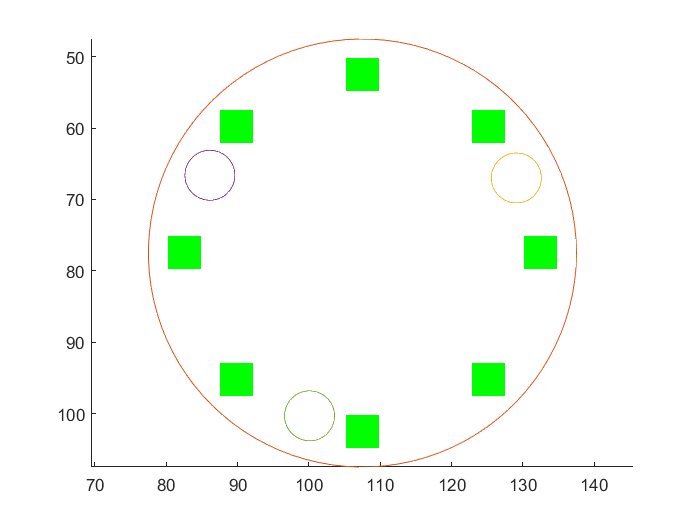

set(gca,'ydir','reverse')
hold off

u = symunit;
battery_capacity = 3.5*([u.A]*[u.h]);%Ah
nominal_voltage = 3.7*[u.V];
buck_efficiency = .95;
capacitance = 1.5*[u.C]/[u.V];
charging_voltage = 5*[u.V];
charge_efficiency = 0.5;
energy_per_cap_charge = 1/2*capacitance * charging_voltage^2 * 1/3600 * [u.V]*[u.A]*[u.h] / [u.J] * [u.J]/([u.V] * [u.C])

$$energy\_per\_cap\_charge = 0.0052\,A\,V\,h$$

LED_power_draw = 8*5*[u.V]*.05*[u.A];%each LED draws 50mA @ 5V, source 
% https://www.pololu.com/product/2547#:~:text=Each%20RGB%20LED%20draws%20approximately%2050%20mA%20when%20it%20is,and%20powered%20at%205%20V.
ESP_power_draw = 5*[u.V] * [.070 .300]*[u.A];% assume 70-300mA current draw @ 5V (voltage is at 5V from the LDO that powers the ESP)
%https://www.esp8266.com/viewtopic.php?t=3875
battery_energy = battery_capacity*nominal_voltage;
battery_life = buck_efficiency * battery_energy ./ (LED_power_draw+ESP_power_draw) %h

$$battery\_life = \left(\begin{array}{cc} 5.2351\,h & 3.5150\,h \end{array}\right)$$

battery_life_loss_one_cap_discharge = battery_life - buck_efficiency * (battery_energy - energy_per_cap_charge/charge_efficiency) ./ (LED_power_draw+ESP_power_draw) %h

$$battery\_life\_loss\_one\_cap\_discharge = \left(\begin{array}{cc} 0.0042\,h & 0.0028\,h \end{array}\right)$$

%assume all other components are negligible in power draw

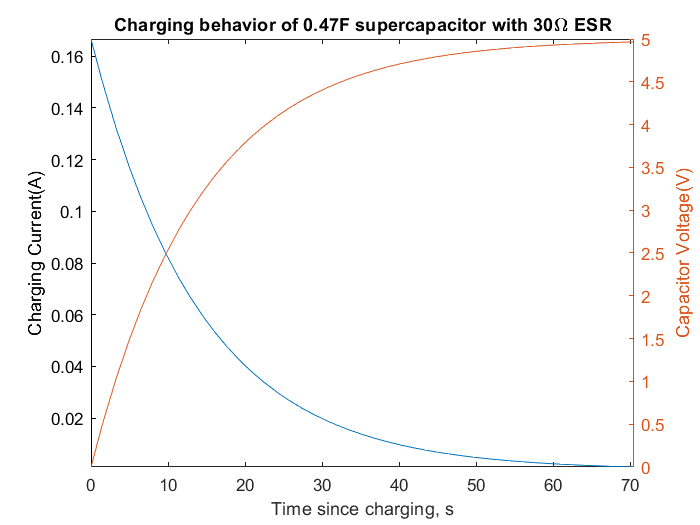

%supercapacitor charging
clear all
close all
syms t T
R = 30;
C = .47;
tau = R*C;
Vmax = 5;
V(t) = Vmax * (1-(exp(-t/tau)));
I(t) = Vmax/R * exp(-t/tau);
fplot(I(t))
hold on
ylabel("Charging Current(A)")
yyaxis right
fplot(V(t))
ylabel("Capacitor Voltage(V)")
xlim([0 5*tau])
xlabel("Time since charging, s")
title('Charging behavior of 0.47F supercapacitor with 30\Omega ESR')
hold off
nexttile

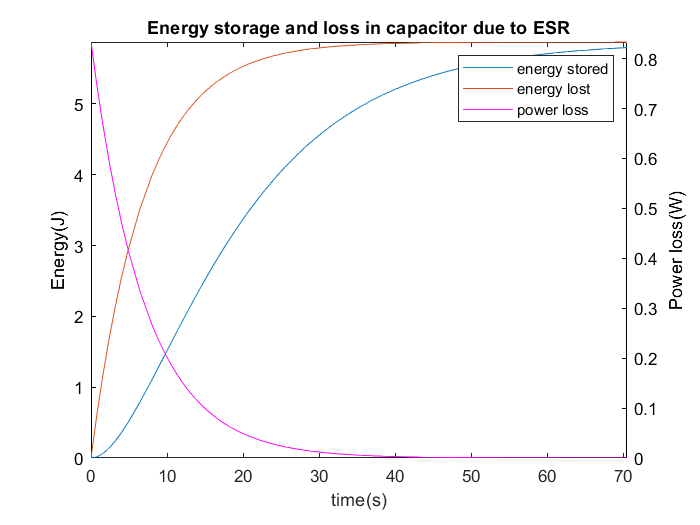

U(t) = int(I(t)*V(t));
constant = U(0);
U(t) = U(t) - constant;
fplot(U(t))
hold on
power_loss(t) = I(t)^2 * R;
energy_loss(t) = int(power_loss(t));
constant = energy_loss(0);
energy_loss(t) = energy_loss(t) - constant;
fplot(energy_loss(t))
xlim([0 5*tau])
ylabel('Energy(J)')
yyaxis right
fplot(power_loss(t), 'm')
ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';
hold off
legend('energy stored', 'energy lost', 'power loss')
ylabel("Power loss(W)")
xlabel('time(s)')
title('Energy storage and loss in capacitor due to ESR')

steel_wool_weight = 4;
c = .046;
solve(U(70) == steel_wool_weight * c * T,T)

$$ans = 31.4851$$

drain_tau = 10000 * C/60

drain_tau = 78.3333

%reset circuit
clear all
close all
t = linspace(0,.1);
Vcc = 3.3;
R = 10000;
C = 10^-6;
V_low = Vcc .* exp(-t./(R*C));

t_new = t + max(t);
V_high = Vcc .* (1-exp(t/(-R*C)));

times = [t t_new];
Voltage_curve = [V_low V_high];
plot(times, Voltage_curve)
hold on
plot([0 max(t_new)], [.25 * Vcc .25*Vcc])
plot([0 max(t_new)], [.75 * Vcc .75*Vcc])
enable_delay_time = min(t(V_low <= .25 * Vcc));
enable_delay_time_ms = 1000 * min(t(V_low <= .25 * Vcc))

enable_delay_time_ms = 14.1414

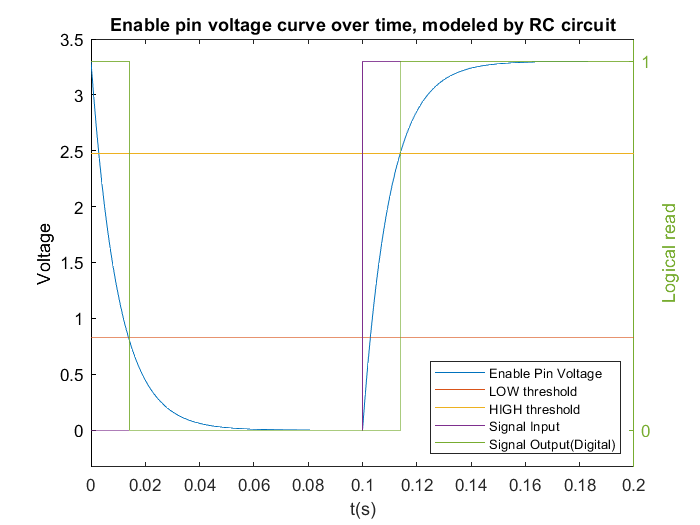

drain_tau = 0.0100

input_curve = Vcc * [0 0 1 1];
input_time = [0 0.1 0.1 0.2];
plot(input_time,input_curve)
ylabel("Voltage")
ylim([-0.1*3.3 3.5])
yyaxis right
plot([0, enable_delay_time, enable_delay_time, enable_delay_time + 0.1, enable_delay_time + 0.1, 0.2], [1 1 0 0 1 1])
legend(["Enable Pin Voltage", "LOW threshold", "HIGH threshold", "Signal Input", "Signal Output(Digital)"],'FontSize',8, 'location', 'southeast')
ylabel("Logical read")
ylim([-0.1 3.5/3.3])
yticks([0 1])
xlabel("t(s)")
title("Enable pin voltage curve over time, modeled by RC circuit")
hold off

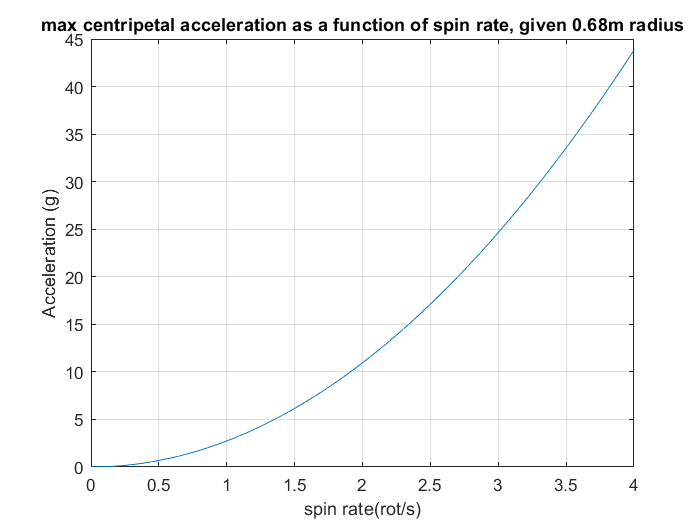

clear all
close all
r = .68;
spin_rate = linspace(0,4);
accel_gs = (spin_rate * 2 * pi) .^2 * r/9.8;
plot(spin_rate, accel_gs)
xlabel("spin rate(rot/s)")
ylabel("Acceleration (g)")
title("max centripetal acceleration as a function of spin rate, given 0.68m radius")
grid on

%POS file
PCB_x = [3.409 3.651 3.997];
PCB_y = [2.289 2.634 2.457];
POS_x = [-20.8964 -14.761 -5.9726];
POS_y = [19.35115 10.576 15.0746];
x = polyfit(PCB_x,POS_x,1);
cap_pcb_x = 3.785468543;
cap_pos_x = x(1) * cap_pcb_x + x(2)

cap_pos_x = -11.3435

y = polyfit(PCB_y, POS_y, 1);
cap_pcb_y = 2.373750512;
cap_pos_y = y(1) * cap_pcb_y + y(2)

cap_pos_y = 17.1943